% ==========================================================
% main_generator.m - 主数据生成脚本
% ==========================================================
clear; clc; close all;

% --- 1. 公共参数设置 ---
params.fs = 80e6;       % 采样频率 100MHz
params.fc = 40e6;        % 中心频率 40MHz
params.B = 10e6;         % 带宽    10MHz
params.taup = 10e-6;     % LFM脉宽 10us
params.Np = 1;          % 脉冲个数 1  ->只在单个PRI内测试
params.PRI = 200e-6;     % 脉冲重复间隔 us
params.SNR = 15;         % 信噪比
% params.JNR = 15;         % 干信比 (可以为不同干扰类型单独设置)
params.pos = 1000;       %在PRI中第5000点处
% JNR_values = 5:5:50;    %干噪比范围 dB
JNR_values = 15;    % 干噪比范围 dB
params.numClasses = 10;    % 基础九种干扰
SAMPLE_NUM_S = 2;
SAMPLE_NUM_M = 5;

% --- 2. 生成计划 ---
% 定义要生成的干扰类型和对应的标签
generation_plan = {
    % 欺骗干扰
    'DFTJ', 1, SAMPLE_NUM_S;
    'ISRJ', 2, SAMPLE_NUM_S;
    'SMSPJ' , 10, SAMPLE_NUM_S;
    % 'RGPO' , 3, SAMPLE_NUM;
    % 'VGPO' , 4, SAMPLE_NUM;
    % 压制干扰
    % 'AJ'  , 5, SAMPLE_NUM_S;
    % 'BJ'  , 6, SAMPLE_NUM_S;
    % 'SJ'  , 7, SAMPLE_NUM_S;
    % 'NCJ' , 8, SAMPLE_NUM_S;
    % 'NPJ' , 9, SAMPLE_NUM_S;
    % 在这里添加更多类型，例如 'sweep', 3, 200
    % 'DFTJ+AJ', [1,5] , SAMPLE_NUM_M;
    % 'DFTJ+BJ', [1,6] , SAMPLE_NUM_M;
    % 'DFTJ+SJ', [1,7] , SAMPLE_NUM_M;
    % 'DFTJ+NCJ', [1,8] , SAMPLE_NUM_M;
    % 'DFTJ+NPJ', [1,9] , SAMPLE_NUM_M;
    % 
    % 'ISRJ+AJ', [2,5] , SAMPLE_NUM_M;
    % 'ISRJ+BJ', [2,6] , SAMPLE_NUM_M;
    % 'ISRJ+SJ', [2,7] , SAMPLE_NUM_M;
    % 'ISRJ+NCJ', [2,8] , SAMPLE_NUM_M;
    % 'ISRJ+NPJ', [2,9] , SAMPLE_NUM_M;

    % 'RGPO+AJ', [3,5] , SAMPLE_NUM;
    % 'RGPO+BJ', [3,6] , SAMPLE_NUM;
    % 'RGPO+SJ', [3,7] , SAMPLE_NUM;
    % 'RGPO+NCJ', [3,8] , SAMPLE_NUM;
    % 'RGPO+NPJ', [3,9] , SAMPLE_NUM;
    %
    % 'VGPO+AJ', [4,5] , SAMPLE_NUM;
    % 'VGPO+BJ', [4,6] , SAMPLE_NUM;
    % 'VGPO+SJ', [4,7] , SAMPLE_NUM;
    % 'VGPO+NCJ', [4,8] , SAMPLE_NUM;
    % 'VGPO+NPJ', [4,9] , SAMPLE_NUM;

    };

% --- 3. 执行生成 ---
[tx, params] = generate_0base_signal(params);

## 循环生成每种干扰

len = size(generation_plan, 1);
SAMPLE_NUM = sum( [generation_plan{:, 3}])

SAMPLE_NUM = 6

for current_jnr = JNR_values
    % 初始化数据容器
    SAMPLE_NUM_S
    all_times = zeros(SAMPLE_NUM,params.PRI_samp);
    all_label = zeros(SAMPLE_NUM,params.numClasses);
    all_stfts = zeros(SAMPLE_NUM,64,249);
    for i = 1:len
        % 生成基础目标信号 (所有干扰类型共用)
        params.pos = 5000+randi([-2000 2000]);
        [tx, params] = generate_0base_signal(params);

        jam_type = generation_plan{i, 1};
        label = generation_plan{i, 2};
        num_to_generate = generation_plan{i, 3};
        fprintf('正在生成 %d 个 [%s] 类型的样本, 标签为 %s...\n', num_to_generate, jam_type, num2str(label));

        Aj = 10^(current_jnr/20);
        % 创建当前SNR值的子文件夹
        % 获取当前时间
        current_datetime = datetime('now', 'Format', 'yyMMdd');
        % 转换为字符串
        time_str = char(current_datetime);
        % 构建目录路径
        snr_output_dir = fullfile(time_str, sprintf('JNR_%+d', current_jnr));

        if ~exist(snr_output_dir, 'dir')
            mkdir(snr_output_dir);
        end
        % fprintf('Generating data for JNR = %d dB...\n', current_jnr);
        %%% jam_type,params,current_jnr,all_labels

        [new_times, new_label] = multi_generation(label,params,current_jnr,num_to_generate);
        point_l = (i-1)*num_to_generate + 1;
        point_r = i*num_to_generate 
        all_times(point_l:point_r,:) = new_times;
        all_label(point_l:point_r,:) = new_label;

        % 追加到总数据集中
    end
    for i = 1:SAMPLE_NUM
        [S,F,T] = spectrogram(all_times(i,1:params.PRI_samp),128,128-64,64,params.fs, 'centered');
        all_stfts(i,:,:) = S;
    end
    % 
    path_stfts = fullfile(snr_output_dir, 'train_echo_stfts.mat');
    path_times = fullfile(snr_output_dir, 'train_echo_times.mat');
    path_label = fullfile(snr_output_dir, 'train_echo_label.mat');

    % path_stfts = fullfile(snr_output_dir, 'val_echo_stfts.mat');
    % path_times = fullfile(snr_output_dir, 'val_echo_times.mat');
    % path_label = fullfile(snr_output_dir, 'val_echo_label.mat');

    % path_stfts = fullfile(snr_output_dir, 'test_echo_stfts.mat');
    % path_times = fullfile(snr_output_dir, 'test_echo_times.mat');
    % path_label = fullfile(snr_output_dir, 'test_echo_label.mat');

    save(path_stfts, 'all_stfts', '-v7.3');
    save(path_times, 'all_times', '-v7.3');
    save(path_label, 'all_label', '-v7.3');
end

SAMPLE_NUM_S = 2

正在生成 2 个 [DFTJ] 类型的样本, 标签为 1...


point_r = 2

正在生成 2 个 [ISRJ] 类型的样本, 标签为 2...


point_r = 4

正在生成 2 个 [SMSPJ] 类型的样本, 标签为 10...


point_r = 6

## 绘图

idx = 1

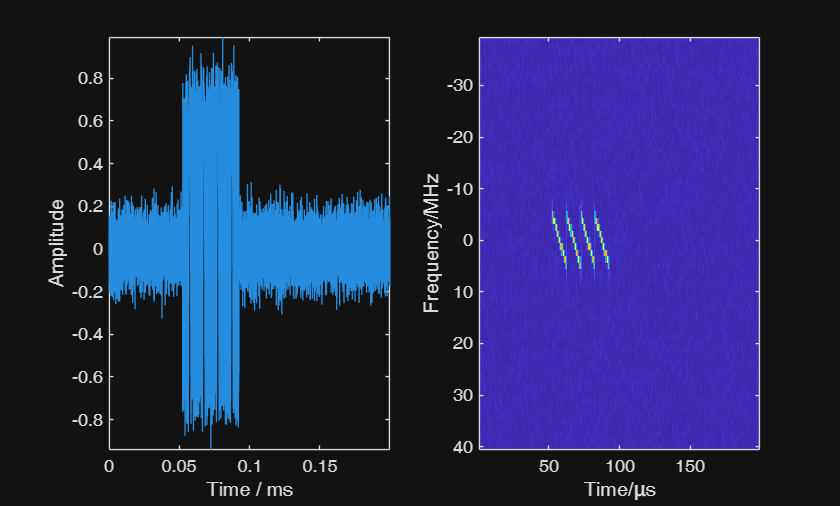

idx = 3

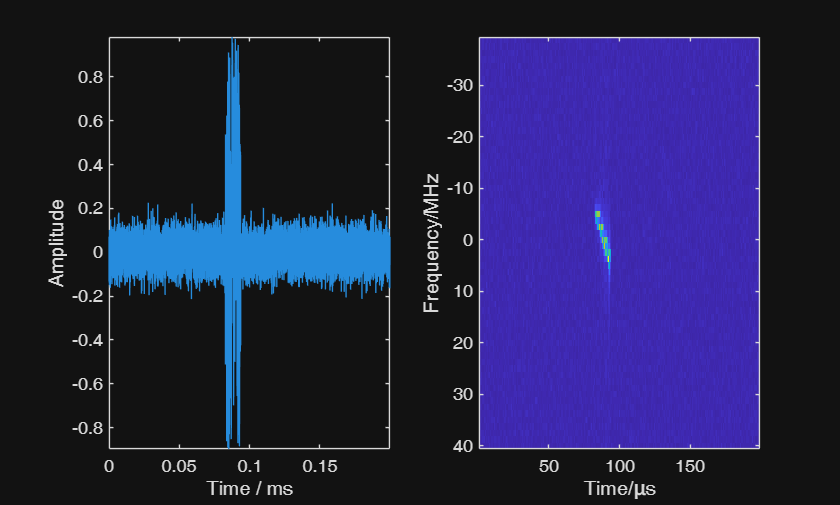

idx = 5

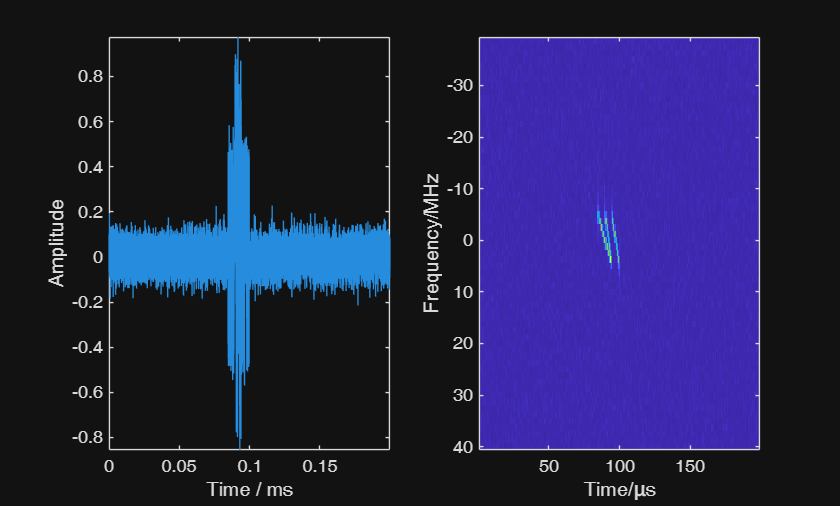

len = size(generation_plan, 1);
idx = -1;
for i =1:len
    idx = idx + generation_plan{i, 3}
    rx = all_times(idx,:);
    figure(i);
    subplot(1,2,1);
    plot(params.t_total*1e3, real(rx));
    % axis([0 3.2 -1.1 1.1])
    axis tight;
    xlabel('Time / ms'); ylabel('Amplitude');

    subplot(1,2,2);

    [S,F,T] = spectrogram(rx(1:params.PRI_samp),128,128-64,64,params.fs, 'centered');
    % S = all_S(50*i-49,:,:);
    S = squeeze(S);
    imagesc(T*1e6,F/1e6,abs(S));
    xlabel('Time/μs'); ylabel('Frequency/MHz');
end

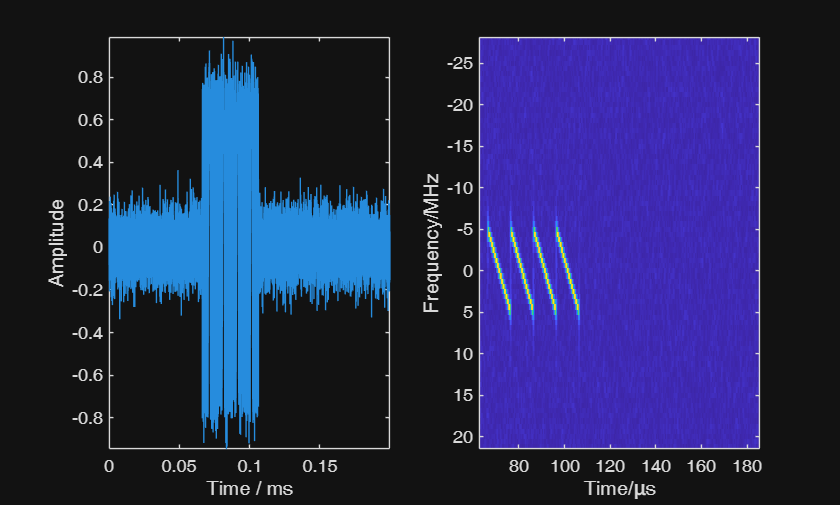

% % --- 5. 保存数据到 HDF5 文件 ---
% fprintf('总共生成了 %d 个样本。\n', size(all_samples, 1));
% output_filename = 'radar_samples.h5';
% % 将复数数据分解为实部和虚部，并转换为 single 精度
% all_samples_real = single(real(all_samples));
% all_samples_imag = single(imag(all_samples));
% all_labels_single = single(all_labels); % 标签也可以是 single 或 int
% % 确保文件不存在，否则 h5create 会报错
% if exist(output_filename, 'file')
%     delete(output_filename);
% end
% % 创建 HDF5 数据集并写入数据
% % 设置 chunking 和 compression 可以进一步优化存储和读取性能
% % 'Compression', 'gzip', 'ChunkSize', [100, size(all_samples, 2)] 是常用设置
% h5create(output_filename, '/samples_real', size(all_samples_real), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_real,1)), size(all_samples_real, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_real', all_samples_real);
% h5create(output_filename, '/samples_imag', size(all_samples_imag), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_imag,1)), size(all_samples_imag, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_imag', all_samples_imag);
% h5create(output_filename, '/labels', size(all_labels_single), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_labels_single,1)), size(all_labels_single, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/labels', all_labels_single);
% disp(['数据已成功保存到 ', output_filename, ' 文件中。']);
rx = all_times(2,:);
figure(i);
subplot(1,2,1);
plot(params.t_total*1e3, real(rx));
% axis([0 3.2 -1.1 1.1])
axis tight;
xlabel('Time / ms'); ylabel('Amplitude');

subplot(1,2,2);

[S,F,T] = spectrogram(rx(1:params.PRI_samp),128,126,128,params.fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
xlabel('Time/μs'); ylabel('Frequency/MHz');